# Analysing neural recordings using the Brain Observatory Toolbox

**The Allen Brain Observatory**

The Brain Observatory project collected data from a range of mouse visual areas, at a range of imaging depths, with indicator expression produced under several transgenic lines, and using a number of visual stimuli. For detailed information about experimental conditions and stimuli, see the [Brain Observatory website](http://observatory.brain-map.org/visualcoding/).

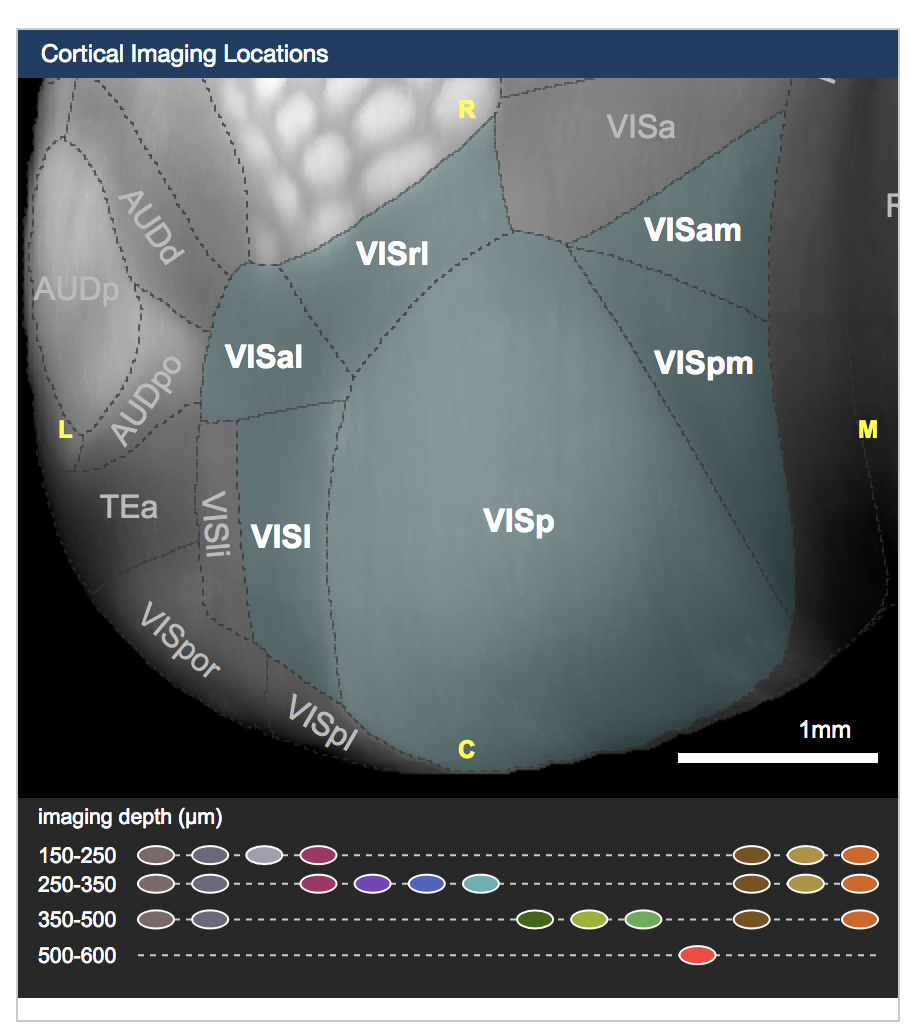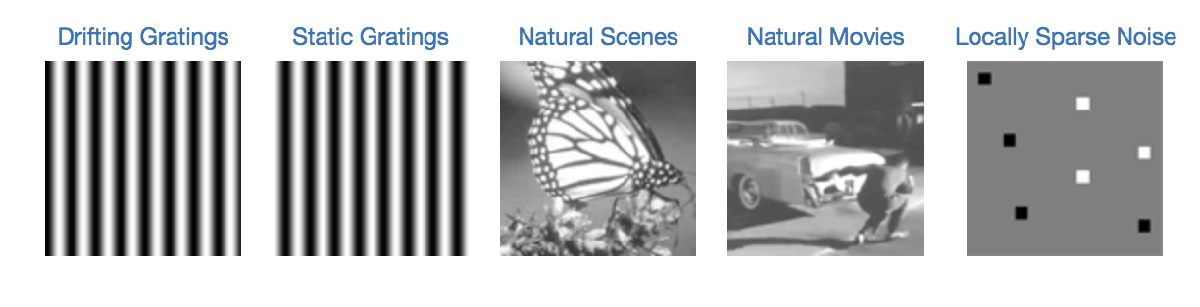

This tutorial demonstrates how to access data from the Allen Brain Observatory ([http://observatory.brain-map.org/visualcoding/](http://observatory.brain-map.org/visualcoding/)), and how to perform some simple analyses of visual responses in neurons in mouse primary visual cortex. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

**Searching and filtering experimental data**

Our goal is to analyse visually responsive neurons in V1. We need a data set from primary visual cortex, in which drifting grating stimuli were presented, and where the behavioural state of the animal was tracked. Listing, filtering and searching through the experimental data is managed by the `bot.sessionfilter` class.

% Get a session filter object
bosf = bot.sessionfilter;

% Select experiments from primary visual cortex ('VISp')
bosf.filter_sessions_by_targeted_structure('VISp');

% Select experiments with drifting grating and natural movie stimuli
bosf.filter_sessions_by_stimuli('drifting_gratings');
bosf.filter_sessions_by_stimuli('natural_movie_one');

% Select experiments where Layer 2/3 was imaged
bosf.filter_sessions_by_imaging_depth(275);

% Select experiments with GCaMP6f expression targetted to Layers 2–4
bosf.filter_session_by_cre_line('Cux2-CreERT2');

% Select experiments with eye tracking data available
bosf.filter_session_by_eye_tracking(true);

% Take the first matching experiment
sessions = bosf.get_filtered_sessions();
session = sessions(1)

session =   session with properties:

               sSessionInfo: [1×1 struct]
    strLocalNWBFileLocation: '/Users/dylan/Development/Brain-Observatory-Toolbox_GIT/+bot/Cache/external/neuralcoding/prod12/specimen_517649990/ophys_experiment_531006860/531006860.nwb'


## Examine an overview of the imaging data

Let's look at the imaged field, by visualizing the maximum intensity projection of the data. By examining the session metadata we can see that the field of view is 400x400µm (512x512 pixels). We can plot a scale bar appropriately.

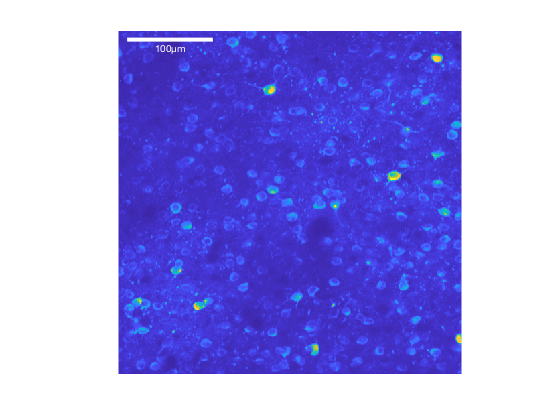

pixelSize = 400/512;
xLocations = linspace(0, 400-pixelSize, 512) + pixelSize / 2;
figure;
imagesc(xLocations, xLocations, session.get_max_projection());
colormap default;
axis square tight off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

Helpfully, the locations and shapes of ROIs defining each neuron are supplied to us from the Brain Observatory data. We can access these ROIs using the `get_roi_mask() `method. This method returns a structure containing ROIs than can be plotted and manipulated using Matlab built-in commands.

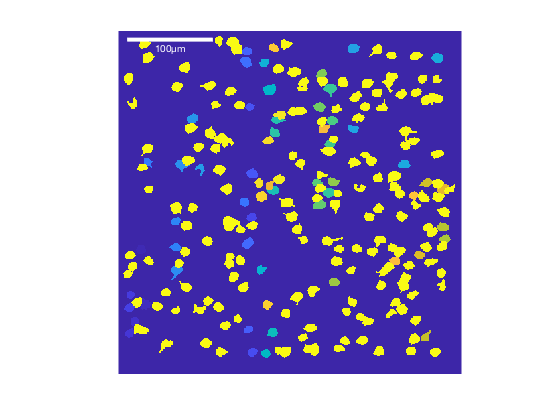

ROIs = session.get_roi_mask();
figure;
image(xLocations, xLocations, labelmatrix(ROIs));
axis tight square off;
hold all;
plot([10, 110], [10, 10], 'w-', 'LineWidth', 4);
text(60, 20, '100µm', 'Color', 'w', 'HorizontalAlignment','center');

## Analysing cell responses

Now let's get access to the fluorescence traces for all ROIs, using the `get_dff_traces()` method. This method returns a `[Tx1]` vector of timestamps, and a `[TxN]` matrix of fluorescence responses for each cell, at each corresponding timestamp.

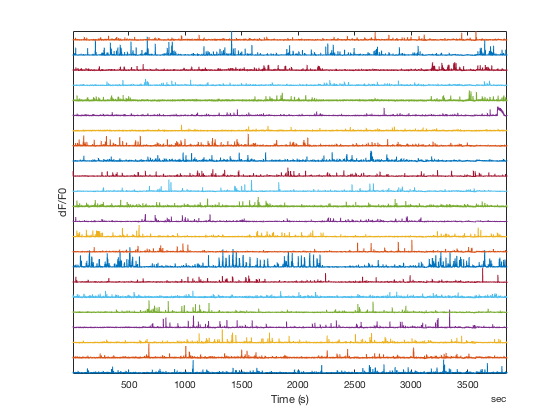

[timestamps, traces] = session.get_dff_traces();
figure;
plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

Not all cells respond equally, as is clear from the traces above. One approach to select ROIs with robust responses is to measure the skewness of the individual responses over time. Neurons that fire sparsely result in a rapid spike in fluorescence emitted photons, followed by an exponential decay of fluorescence down to the noise level of the system. The resulting distribution of recorded fluorescence values has a positively skewed distribution, compared with Normally distributed white noise which has a theoretical skewness of zero. We can use the built-in Matlab `skewness()` command to estimate the skewness for each ROI.

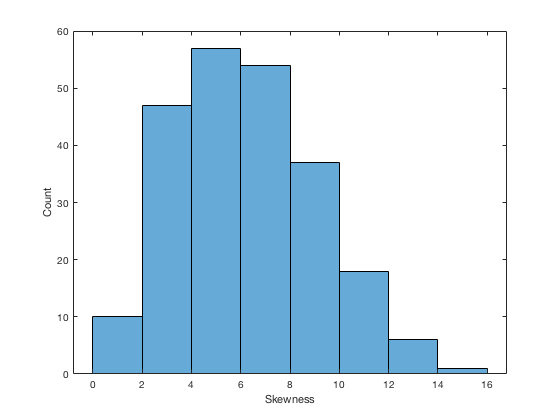

skewness = skewness(traces);
figure;
histogram(skewness);
xlabel('Skewness'); ylabel('Count')

Let's compare the response of a high-skewness ROI with a low-skewness ROI.

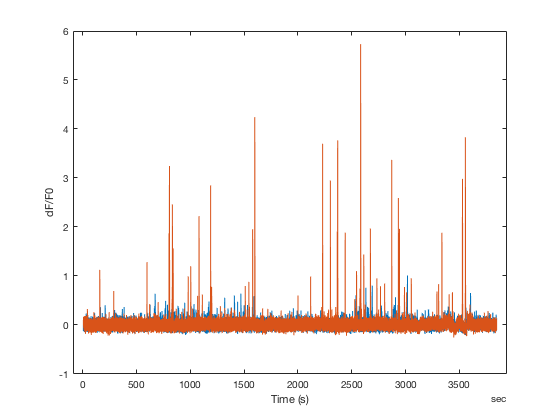

[~, sortOrder] = sort(skewness);
plot(timestamps, traces(:, sortOrder([5 end])))
xlabel('Time (s)'); ylabel('dF/F0');

Generally a skewness threshold of 1 or 2 is sufficient, which leaves the majority of cells in this experiment.

## Analysing stimulus responses

This animal was presented with an array of stimuli, including drifting sine-wave grating stimuli. Let's find the responses to individual trials of the drifting gratings, separated by drift direction, and build tuning curves for each ROI.

% Get the stimulus information for drifting grating responses
driftingGratings = session.get_stimulus_table('drifting_gratings');

% Use a utility function to estimate single-trial responses for each stimulus
responses = bot.util.StimulusAlignedResp(driftingGratings, traces);

% Locate "blank" stimulus presentations
vbBlankPresentations = driftingGratings{:, 'blank_sweep'} == 1;

% Extract neural responses to blank presentations
blankResponses = nanmean(responses(vbBlankPresentations, :));

% Subtract blank responses
responsesCorrected = responses - blankResponses;

Each particular visual stimulus was presented multiple times. We therefore need to collect and sort responses to multiple trials of the same visual stimulus. We will assign a unique stimulus ID to each stimulus, using the built-in function `unique()`.

% Get a list of unique stimulus parameters and assign a stimulus ID to each presentation
[uniqueStimuli, ~, presentationStimID] = unique(driftingGratings(:, 1:2), 'rows', 'sorted');

Each presentation is now assigned a stimulus ID, listed in `vnPresentationStimID`, which corresponds to the stimulus parameters in rows of `tUniqueStimuli`. We can now collect 